M130 Midterm

Start by checking the image properties of your assigned image and loading it into MATLAB

%Load your image
info = imfinfo('Image_10.tif');
length(info)

ans = 36

info(1).Width

ans = 649

info(1).Height

ans = 536

info(1).BitDepth

ans = 16

info(1).ColorType

ans = 'grayscale'

disp("The size of the image is 649x536 , with 36 pages")

The size of the image is 649x536 , with 36 pages


img = zeros(info(1).Height, info(1).Width, length(info), 'uint16'); 
% for loop to read in the data 
for i = 1:length(info) 
    img(:,:, i) = imread('Image_10.tif', i); 
end

max(img(:)) % this will help us with the range determination, 

ans = uint16
9136

min(img(:)) % this will help us with the range determination, no black images 

ans = uint16
65

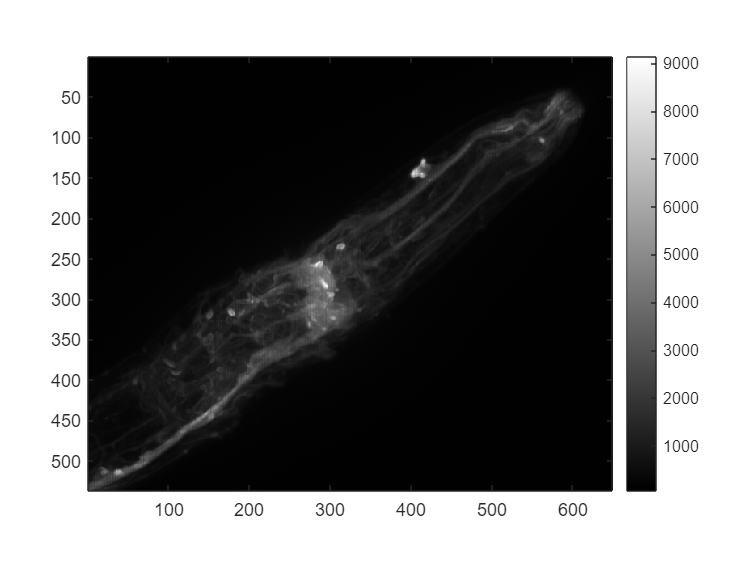

%Compute a max projection of your image and display it (1 point)
max_proj = max(img,[],3);
figure;
imagesc(max_proj,[min(img(:)),max(img(:))])
colormap gray 
axis image
colorbar

%sliceViewer(img, "DisplayRange", [65, 9136])

%Compute the Fourier Transform of your max projection image and display the
%real values of the Fourier Transform (2 points)
%Remember that the FT image has to be rearranged to display correctly using
%the fftshift command   

ft = fft2(max_proj);
ft_shift = fftshift(ft); 
ft_real = abs(ft)

ft_real = 1.0e+08 *

    1.5406    0.3704    0.0981    0.1069    0.0585    0.1333    0.0541    0.0737    0.0157    0.0504    0.0533    0.0298    0.0145    0.0050    0.0186    0.0340    0.0124    0.0072    0.0066    0.0180    0.0064    0.0105    0.0073    0.0140    0.0067    0.0031    0.0078    0.0056    0.0080    0.0094    0.0008    0.0041    0.0026    0.0069    0.0038    0.0042    0.0061    0.0024    0.0061    0.0039    0.0059    0.0042    0.0023    0.0014    0.0069    0.0021    0.0073    0.0050    0.0029    0.0072
    0.3960    0.9314    0.2143    0.0720    0.0628    0.0476    0.1013    0.0625    0.0696    0.0053    0.0389    0.0371    0.0297    0.0147    0.0087    0.0095    0.0200    0.0169    0.0085    0.0046    0.0125    0.0057    0.0111    0.0055    0.0094    0.0065    0.0089    0.0076    0.0019    0.0046    0.0062    0.0029    0.0033    0.0019    0.0081    0.0007    0.0046    0.0045    0.0022    0.0061    0.0029    0.0048    0.0027    0.0025    0.0014    0.0049    0.0034    0.00

disp('for better visualization, shift 0-frequency component to the center')

for better visualization, shift 0-frequency component to the center


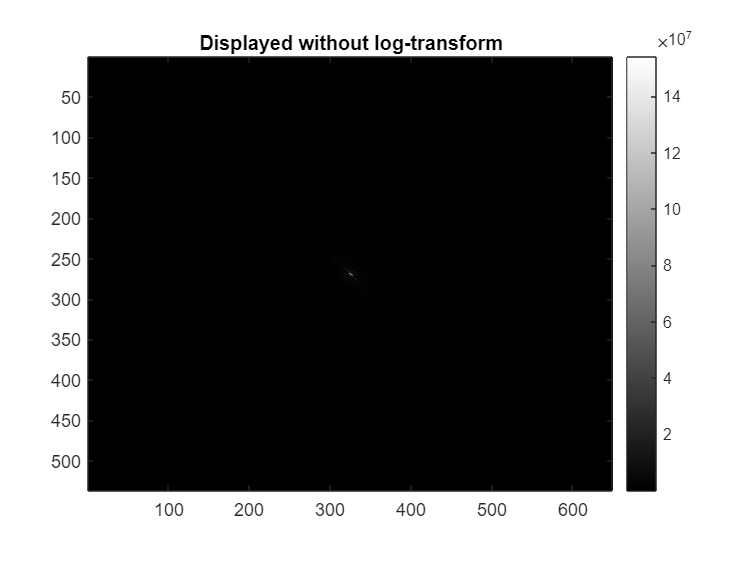


figure
imagesc(abs(ft_shift))

colormap gray
axis image
colorbar
title("Displayed without log-transform")

disp('We notice a single bright dot at 330/260, now we will adopt log-transform')

We notice a single bright dot at 330/260, now we will adopt log-transform


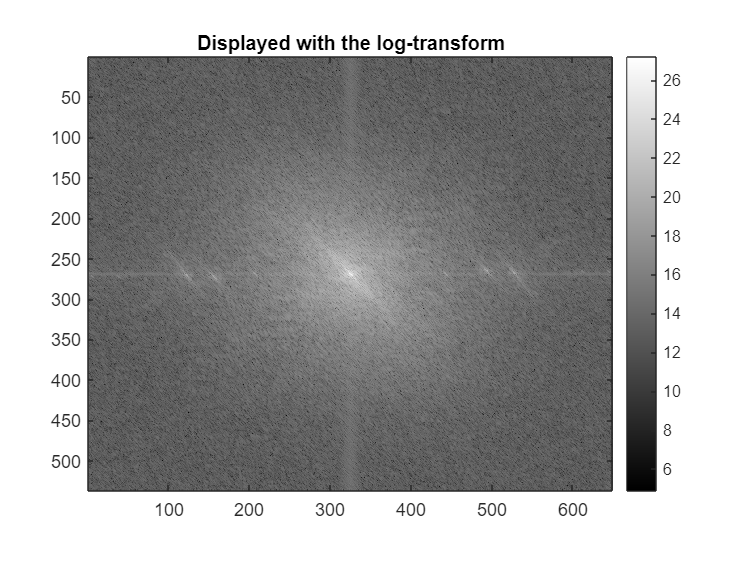


figure
imagesc(log2(1+abs(ft_shift))) 
colormap gray
axis image
colorbar
title("Displayed with the log-transform")

disp('After we have transformed in the log domain, we can better visualize the smaller values')

After we have transformed in the log domain, we can better visualize the smaller values


disp('especially around the high-frequency regions. We have brought down high intensity and brought up low intensity')

especially around the high-frequency regions. We have brought down high intensity and brought up low intensity


disp('We add 1 to avoid log(0), we chose 1 because it is a small number')

We add 1 to avoid log(0), we chose 1 because it is a small number


%Compare the FT image and the original image, as we discussed in class it's
%important to pick a Gaussian kernel that is smaller than the features you
%want preserved when filtering in the spatial domain, and wider than the
%informative range of frequencies in the frequency domain. What is the
%approximate size of the smallest features you want to keep in the image?
%This could be the number of pixels wide narrow edges are, or the number of
%pixels wide the gaps between nuclei are. (2 points)

Type your observations here:

For better visualisation, we shifted the 0 frequency to the center. The original value displayed without log-transform is not informative. We only see a bright dot in the middle of the zero axis, and it represents the overall brightness of the image. 

Comparing my max-projection with its fourier transform, the image I was given has a lot of high frequency-low frequency changes horizontally. This is because we see the log-transformed fourier transform image has a bright vertical streak down the middle. The original timage has thin, elongated structure. This means that signal frequencies follow the cosine wave rule (Lecture 6) whee the original image has more vertical compoenent and the FT image has more balanced horizontal components/pattern (lining up symmetrically). 

Since most of the features in the original image is concentrated in the middle, we can see this reflected in the Fourier Transform image with a vertical streak. The vertical white line in the Fourier Transform must represent the horizontal shift from the spherical nuclei to the dark area near the center of the original image. The smallest spherical features in the image that we want to preserve are roughly 20-30 pixels wide (the nuclei near the middle of the image) and 30 pixels in length.

%Based on the size you noted above, pick a reasonable value for c and
%compute a 2D Gaussian with that value. Display the Gaussian and double
%check that the size of it matches what you were shooting for. Look at the
%FFT of the Gaussian and compare it to the FFT of the original image, is
%the Gaussian wider than the informative range of frequencies in the
%original image? ie. Do you expect that applying the filter will preserve
%those features in the image? (3 points)

% Computing the 2D Gaussian, first we define the Gaussian filter
m = 25;
n = 30;
gaussian = zeros(m,n);
c = 5; % choosing c for the filter 
disp(['Here I am choosing 5 because I have chosen a blob ' ...
    'and found its pixel width and length to be 25x30, ' ...
    'and then I divide that number by 6. We can set the c to be that value.'])

Here I am choosing 5 because I have chosen a blob and found its pixel width and length to be 25x30, and then I divide that number by 6. We can set the c to be that value.


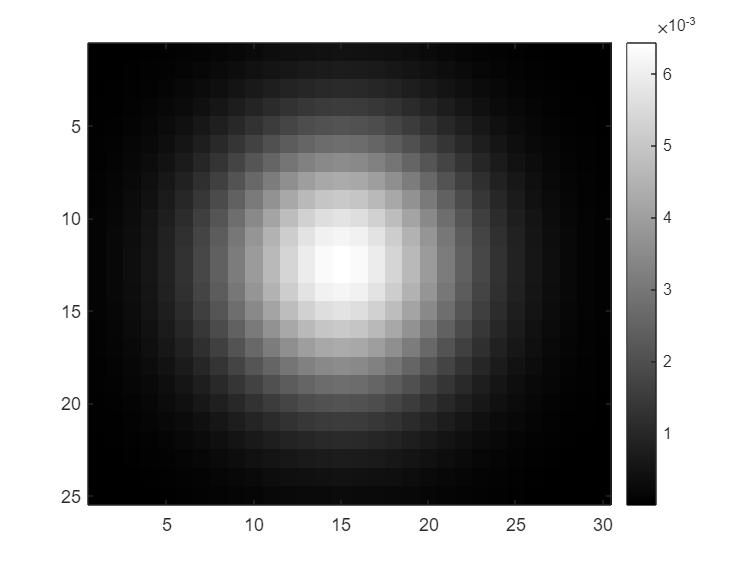


for x=1:n
    for y=1:m
        sq_dist = (x-n/2)^2 + (y-m/2)^2; % distance from the center pixel
        gaussian(y,x) = exp(-1*sq_dist/(2*c*c)); % division by the standard deviation.
    end
end
gaussian = gaussian./sum(gaussian(:)); % to normalize the kernel since we are taking discrete values. 
imagesc(gaussian)
colormap gray
colorbar

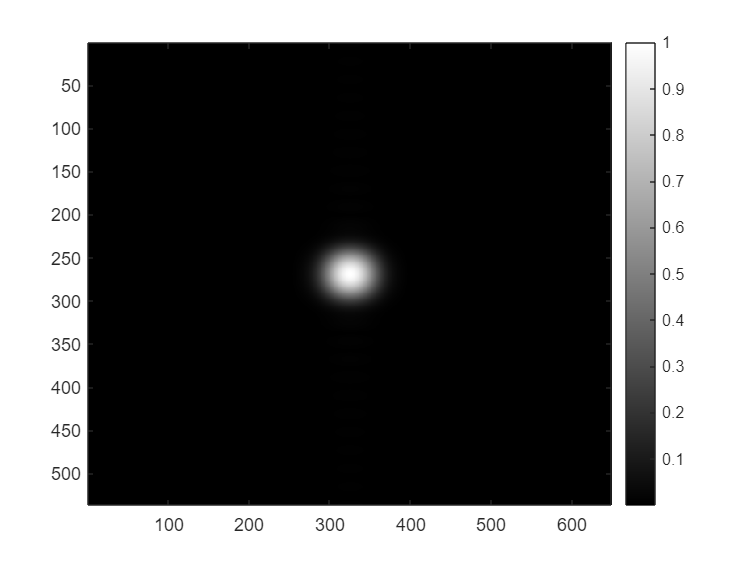

ft_gauss = fft2(gaussian, size(max_proj,1),size(max_proj,2));
shift_ft_gauss = fftshift(ft_gauss);
imagesc(log2(1+abs(shift_ft_gauss)))
colorbar

Type your observations here: Since the smallest features we want to preserve are roughly 30 pixels wide, a c value of 5 (30/6) would be appropriate. Comparing the Fourier Transform of the Gaussian to the Fourier Transform of the original image, it as apparent that the Gaussian is wide enough to cover all the frequency ranges in the original image and will preserve the features. The size of the Gaussian matches the appropriate filter size to be convoluted with. The Gaussian is wider than the informative range of the frequencies in the original image, and I expect applying the filter will retain image features. 

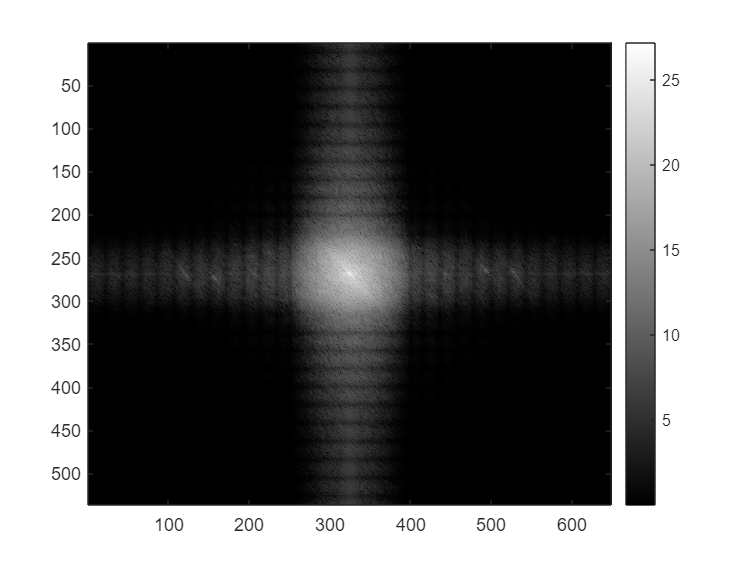

%Apply the filter and compute the inverse fourier transform. Display the
%reconstructed image and compare it with the original. Did you achieve your
%goal? Are the features you found interesting in the original image
%preserved? Has noise been reduced? Are there any unexpected consequences
%for the image? (3 points)

%Applying it over the image, see image in frequency domain.
filtered_ft_img  = ft_shift.*shift_ft_gauss; % perform convolution
imagesc(log2(1+abs(filtered_ft_img)))
colorbar 

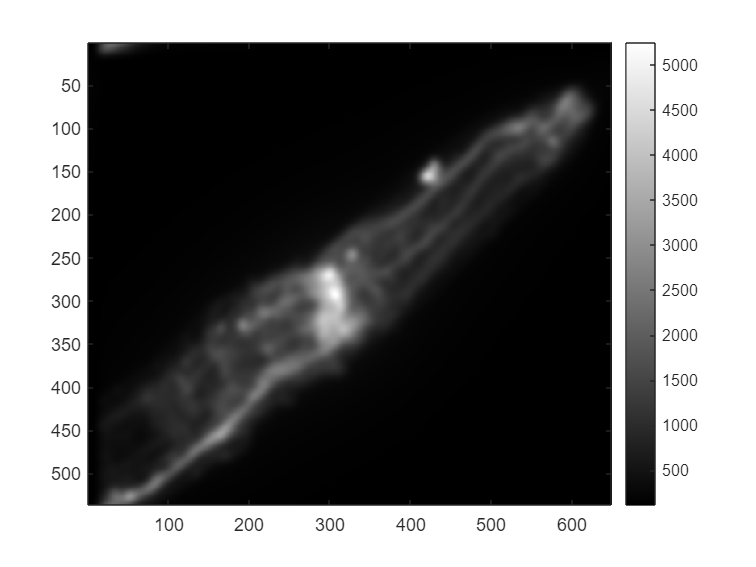

% Computing inverse fft of the image 
new_img = ifft2(ifftshift(filtered_ft_img));
imagesc(abs(new_img))
colormap gray
colorbar

Type your observations here:

Yes, the nuclei observed in the original image has been preserved. The filter has gotten rid of the high frequency noise between each of the nuclei, but has blurred the sharp edges of the image. Overall, there has not been any unexpected consequences for the image. My image contains informative edges and blobs, noticeably in the middle. I have tried using a c = 3, which seems to only detect edges. With a value of c = 5, it was able to pick up blobs in the image. 

We use first derivative of a Gaussian for edge detection, and use the Laplacian of a Gaussian (second derivative) for blob detection in a non-convenient shape. A bigger c can give us a Gaussian kernel that will retain edge-detection ability and blob-detection ability. Perhaps then we sacrifice resolution for blob-detection ability and noise-reduction, but all necessary features are captured so my goal is accomplished. 

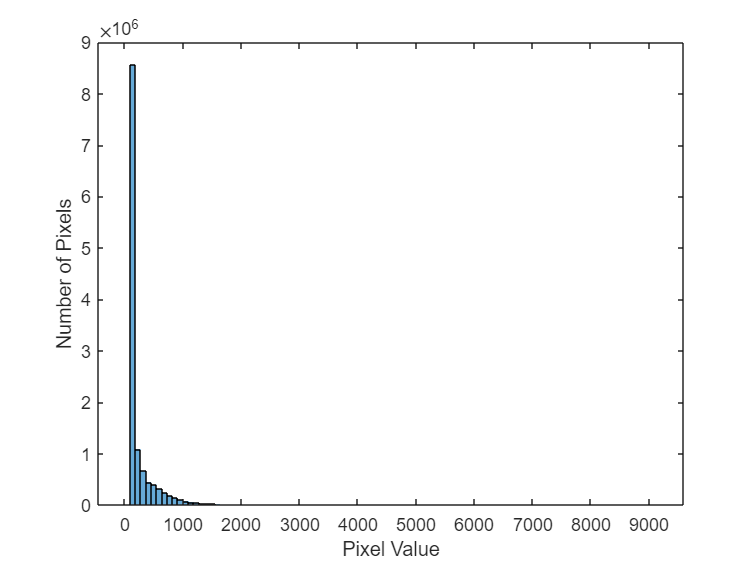

%Pick an appropriate contrast metric for your image based on the
%characteristics of each that we've discussed in class. Apply the contrast
%metric to your original image and to your filtered image, how did noise
%reduction impact the measured contrast of your image? (3 points)

%Trying Weber's contrast first on the original image 
figure; 
histogram(double(img(:)), 100)
xlabel('Pixel Value')
ylabel('Number of Pixels')


thresh = 1500; %I'm picking 1000 because I see that the majority of the pixels lands from 0 to 1500 pixel value, and the tail is located at around 1500 pixel value.
foreground = img > thresh;
background = img <= thresh; 
pixels_in_foregnd = sum(foreground(:))

pixels_in_foregnd = 156308

pixels_in_backgnd = sum(background(:))

pixels_in_backgnd = 12366796

ratio = pixels_in_foregnd/pixels_in_backgnd

ratio = 0.0126

disp('The ratio of # of pixels in the foreground to # of pixels in the background is 0.0021')

The ratio of # of pixels in the foreground to # of pixels in the background is 0.0021


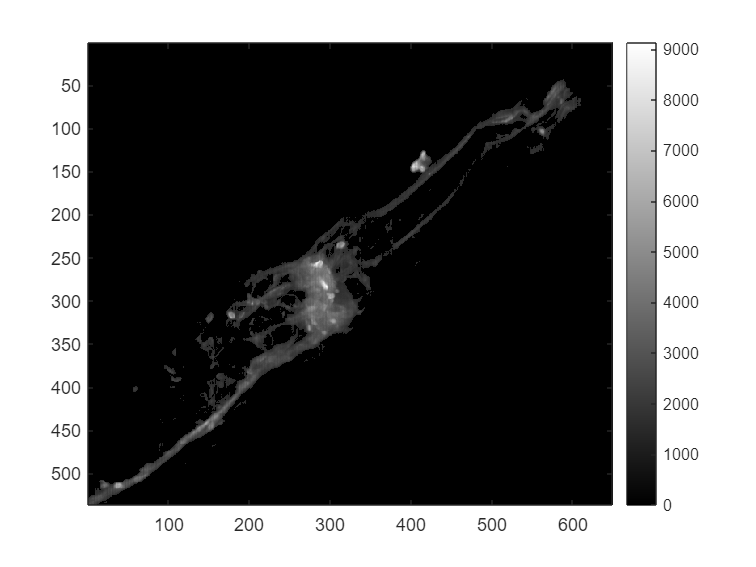

foregnd_img = img.*uint16(foreground);

max_proj_foregnd = max(foregnd_img,[],3);
imagesc(max_proj_foregnd)
colormap gray
colorbar

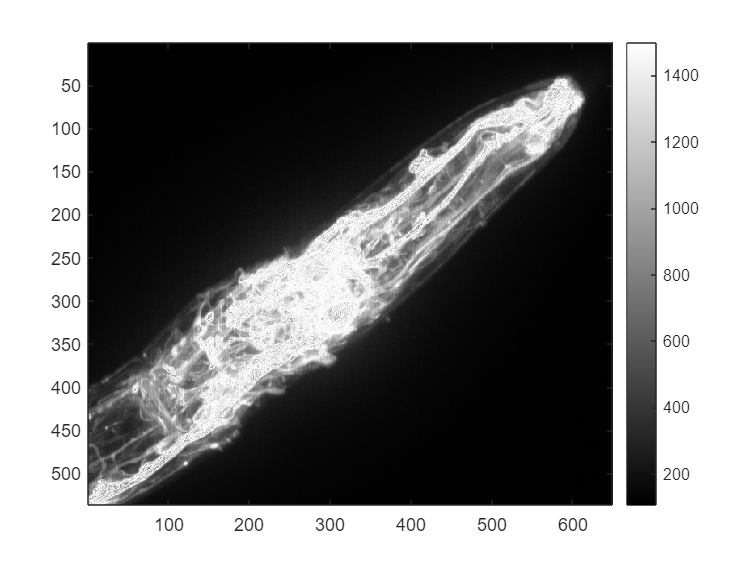


backgnd_img = img.*uint16(background);
max_proj_backgnd = max(backgnd_img,[],3);
imagesc(max_proj_backgnd)
colormap gray
colorbar

mean_img_bkgnd = mean(img(background));
mean_img_fgnd = mean(img(foreground));
Weber = (mean_img_fgnd- mean_img_bkgnd)/mean_img_bkgnd

Weber = 8.9415

disp("The Weber contrast for the original image is 13.4917")

The Weber contrast for the original image is 13.4917


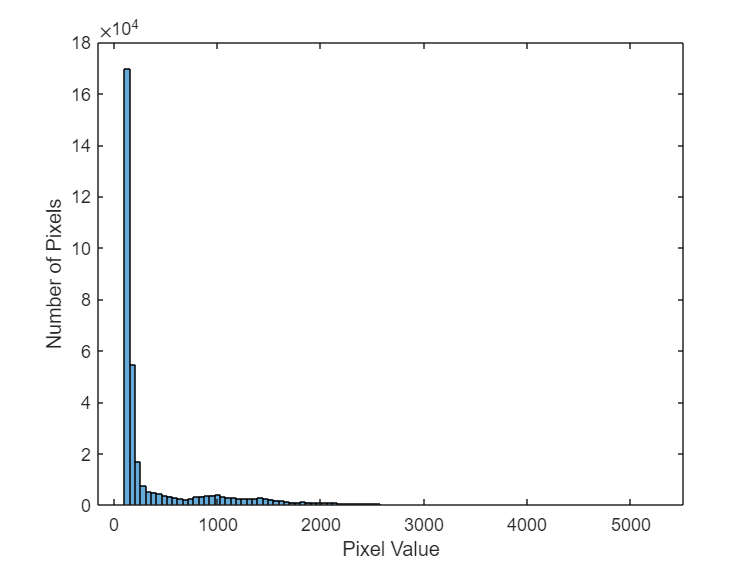


% --------------------------
% Applying the contrast on the filtered image

figure; 
histogram(double(new_img(:)), 100)
xlabel('Pixel Value')
ylabel('Number of Pixels')


thresh = 1500; % I'm picking 1500 because whereas the majority of the pixels lands between pixel value 0-1000 , there are still residual scattering from 1000-1500 pixel value.  
foreground = new_img > thresh;
background = new_img <= thresh; 
pixels_in_foregnd = sum(foreground(:))

pixels_in_foregnd = 24533


pixels_in_backgnd = sum(background(:))

pixels_in_backgnd = 323331

ratio1 = pixels_in_foregnd/pixels_in_backgnd

ratio1 = 0.0759

disp('The ratio of # of pixels in the foreground to # of pixels in the background is 0.3077')

The ratio of # of pixels in the foreground to # of pixels in the background is 0.3077


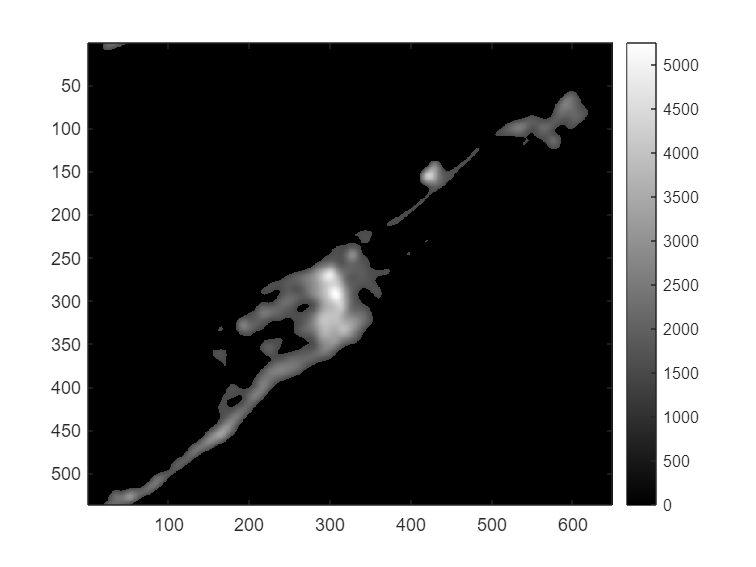


foregnd_img = new_img.*double(foreground);
max_proj_foregnd = max(foregnd_img,[],3);
imagesc(max_proj_foregnd)
colormap gray
colorbar

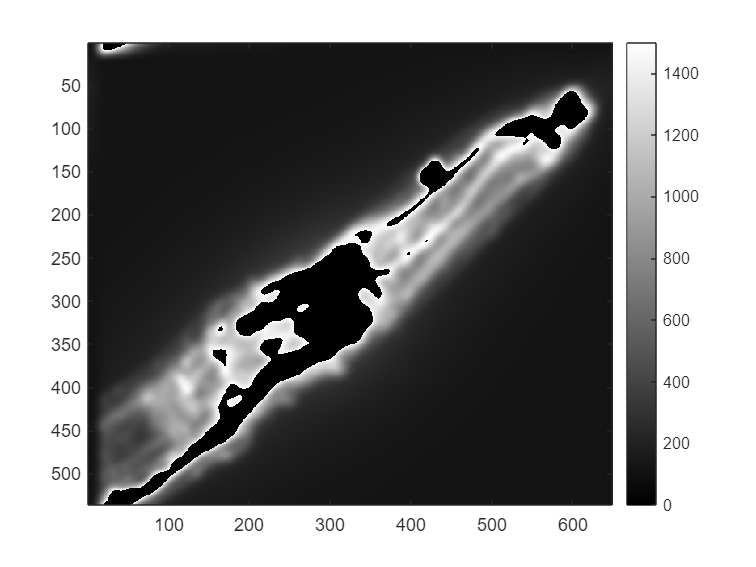


backgnd_img = new_img.*double(background);
max_proj_backgnd = max(backgnd_img,[],3);
imagesc(max_proj_backgnd)
colormap gray
colorbar


mean_img_bkgnd = mean(new_img(background));
mean_img_fgnd = mean(new_img(foreground));
Weber_filtered = (mean_img_fgnd- mean_img_bkgnd)/mean_img_bkgnd

Weber_filtered = 6.1331

disp("The filtered image's Weber contrast is 6.1934")

The filtered image's Weber contrast is 6.1934


Type your observations here:

In this image, the body of the embryo's most important features are not the epidermial layer but the length of the vessels/neural pathways. The image's most important features are accentuated by calibrating the threshold according to the pixel count in the Weber method. Both the Michelson and RMS method do not yield as much contrast (Weber yields up to 3 times more contrast). I should note here that the Weber metric would not be as appropriate if the image is primarily dark (most background is not showing features), and the Weber method is preferred here because we can see the foreground. While the Michelson method does not get impeded by user's need to define heuristics of foreground and background, it is not appropriate for this image. The RMS method is used if there are proportional foreground and background number of pixels, which is not what we see here (we have an abundance of bright cells). 

We should note that noise reduction from filtering has reduced the contrast on the image. When we effectively used blob detection, the body of the embryo has received less contrast. Therefore, the original image has a Weber contrast of 8.94 and the filtered image has a Weber contrast of 6.19.

Share some feedback, what's working for you? what's not working for you? what concepts are you struggling with the most? (1 point)

So far, everything seems to be working alright! I am not yet struggling with any concepts. We'll see. 